% data prep
clear
SetRNG(11);
load fisheriris
inputs_ori = 2*rand(20,2);
inputs_ori = meas(:,[2 4]);% data 1
inputs = inputs_ori-mean(inputs_ori);

% fit linear regression model
mdl = fitlm(inputs(:,1),inputs(:,2));
slope_lr = mdl.Coefficients.Estimate(2);
regression_line = normr([1 slope_lr]);
[coeff_real,~,~,~,explained_1,~] = pca(inputs);
PC1_line = normc(coeff_real(:,1));
o = [0 0];

% run our algorithm
dim = 2;
n_src = dim;
n_dst = 10;
n_per_src = 1;
synaptic_weights_mat = randn(n_src,n_dst);
[srcIdx,dstIdx] = ConnectHypergeometric(n_dst, n_src, n_per_src);
index = [srcIdx;dstIdx];
for i = 1:n_dst;
    nonzero_idx = index(2,find(index(1,:) == i));
    zero_idx = setdiff(1:n_src,nonzero_idx);
    synaptic_weights_mat(zero_idx,i) = 0;
end
 cells = synaptic_weights_mat; %original

epoch = 500;
ori_cycle1_cells = cells;
final_weight = [];

sum1 = [];
test1 = [];
mean1 = [];
for e = 1:epoch;
    imterim_weight = [];
    sampled_data = inputs;
    sampled_data = inputs(randperm(size(inputs, 1)),:);
    mean_sum = [];
    for col = 1:size(sampled_data,1); % loop over all inputs
        lr = 0.0001;
        input1_ori = sampled_data(col,:);% each input
        input1 = input1_ori';
        product = input1'*ori_cycle1_cells;
        signs = sign(product);
        sign2 = sign(input1'*ori_cycle1_cells(:,1));
        sum1 = [sum1;sum(signs)];
        winning_idx = 1:length(product);
        %winning_idx = winning_idx(randperm(length(winning_idx)));
        winning_cell = ori_cycle1_cells(:,winning_idx); % the winning cell set, which may contain more than one winning cell
        update_winner_ori = winning_cell+(signs.*input1-winning_cell)*lr;
        mean_sum = [mean_sum,sign2.*input1];
        update_winner_norm = update_winner_ori;
        ori_cycle1_cells(:,winning_idx) = update_winner_norm;
    end
    mean1 = [mean1,normc(mean(mean_sum,2))];
end
center = normc(ori_cycle1_cells(:,1));

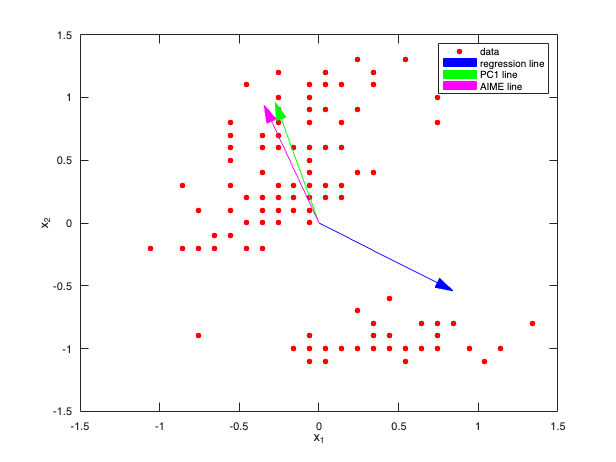

%plot
figure;
plot(inputs(:,1),inputs(:,2),'r.','MarkerSize',15)
arrow(o,regression_line,'Color','b');
arrow(o,PC1_line,'Color','g');
arrow(o,center,'Color','m');
legend('data','regression line','PC1 line','AIME line')
xlabel("x_1")
ylabel("x_2")
ylim([-1.5 1.5])
xlim([-1.5 1.5])

cos_similarity_w_regression = regression_line*center

cos_similarity_w_regression = -0.7965

cos_similarity_w_PC1 = PC1_line'*center

cos_similarity_w_PC1 = 0.9973